# Working with Audio and Images in MATLAB

## Reading Audio

MATLAB can read most audio files. You generally want to read in the signal and the sample rate. The following code reads in the entire sound file and plots it. The code will be a bit slow because it is reading in the entire sound track.

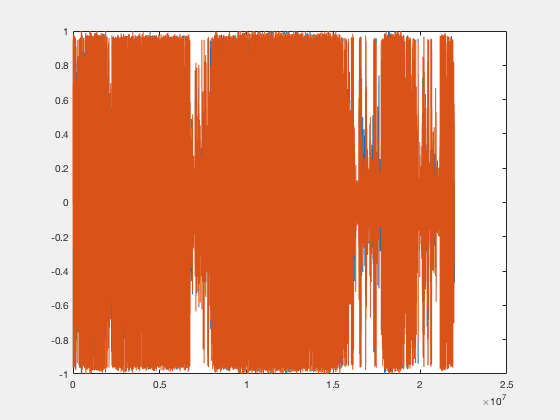

[sig, fs] = audioread('05 - oh, babe.mp3') ;
figure ; set(gcf,'Visible','On')
plot(sig)

**Signal Size:** Let's determine the size of the signal 'sig'.

size(sig)

ans =     21977856           2


This tells us that 'sig' is a matrix with two columns. There are two columns because we read in a stereo signal with a left and right channel.

**Sample Rate:** Let's now determine the sample rate.

fs

fs = 44100

The sample rate is 44100 which is standard for CD music. In most of my reserach I use a sample rate of 48 kHz.

**Length of Signal:** Let's now determine how long the signal is in seconds.

sigLen = length(sig)/fs

sigLen = 498.3641

We divide by the sample rate because there are fs samples per second. We see that the sound track is 498.36 seconds long.

**Read only a section of audio:** It is often useful to read in just a portion of a sound file. We can also do that using audioread. We can read in the first 15 seconds of audio using the following code.

[sig,fs] = audioread('05 - oh, babe.mp3',[1 44100*15]) ;

here, the 1 indicates the start sample to read from and 44100*15 indicates the sample to stop reading.

Alternatively, we can read from 10 seconds to twenty-five seconds using the following code.

[sig,fs] = audioread('05 - oh, babe.mp3',[10 25]*fs) ;

Use the command 'help audioread' to learn more about the audioread function.

help audioread

 audioread Read audio files
    [Y, FS]=audioread(FILENAME) reads an audio file specified by the 
    string FILE, returning the sampled data in Y and the sample rate 
    FS, in Hertz. 
    
    [Y, FS]=audioread(FILENAME, [START END]) returns only samples START 
    through END from each channel in the file.
    
    [Y, FS]=audioread(FILENAME, DATATYPE) specifies the data type format of
    Y used to represent samples read from the file.
    If DATATYPE='double', Y contains double-precision normalized samples.
    If DATATYPE='native', Y contains samples in the native data type
    found in the file.  Interpretation of DATATYPE is case-insensitive and
    partial matching is supported.
    If omitted, DATATYPE='double'.  
    
    [Y, FS]=audioread(FILENAME, [START END], DATATYPE);
 
    Output Data Ranges
    Y is returned as an m-by-n matrix, where m is the number of audio 
    samples read and n 

## Play Audio

**Sound Function**

We can also use MATLAB to play sound. The simplest method is to use either the sound or soundsc function.

The sound function will play the sound without scaling the sound in amplitude.

sound(sig,fs)

Sometimes it is convenient to scale a sound to maximum amplitude before playing it. This will play the soiund as loud as possible without clipping.

soundsc(sig,fs)

We can play just the left or right channel of audio using MATLAB's colon operator. The left channel is usually the first channel. The colon means select any/all rows and the '1' means select the first column.

sound(sig(:,1),fs)

**Audioplayer**

We can also play audio in MATLAB using the audioplayer as follows.

In this example, we play the sound from 5 seconds to 10 seconds. We have to multiply by the sample rate because the play function uses sample numbers.

playObj = audioplayer(sig,fs) ;
play(playObj,[5 10]*fs)

## Record Audio

You can also use MATLAB to record audio. In order to record audio you need to know the device ID for the sound recording device you will be using. You can obtain a list of device IDs by calling RecordAudio with no arguments

RecordAudio

ans = 'Dev: 1 Default'

ans = 'Dev: 2 Built-in Microph'

ans = 1×2 cell array
    'Default'    'Built-in Microph'


Type help RecordAudio to see a list of the inputs and a description of the function. The input arguments are the recording time, the device ID, the sample rate, the buffer size, and a boolean variable that specifies when the user should be prompted to hit a key to start the recording. The following example will record audio for four seconds from the default sound recording device. Note that the default sample rate is 48000 Hz. 

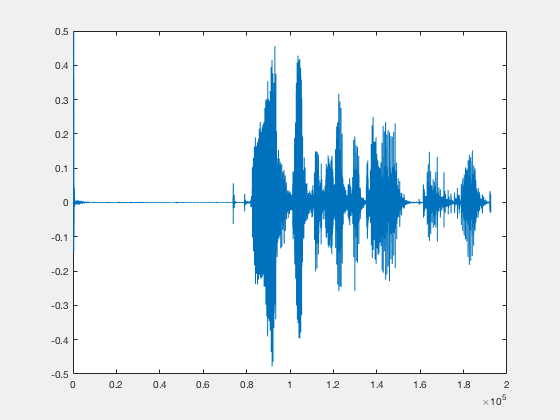

recSig = RecordAudio(4, 1, [], [], false) ;
figure;
set(gcf,'Visible','On')
plot(recSig)

## Play Back the Recorded Audio

sound(recSig,48000)


# Images

## Read Image

MATLAB can read most image files. 

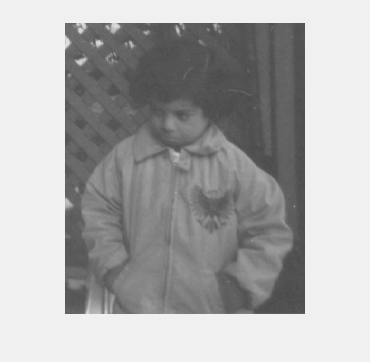

I = imread('pout.tif') ;
imshow(I)
set(gcf,'Visible','On')

## Adjust Image Contrast

We can easily adjust the contrast of the image, specifying contrast limits.

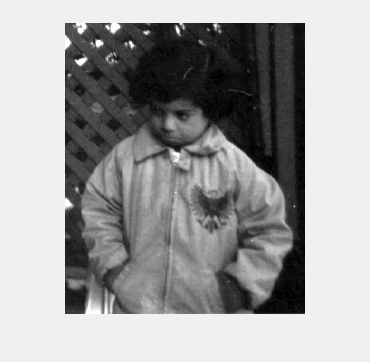

I2 =imadjust(I,[0.3 0.7],[]) ;
figure
imshow(I2)
set(gcf,'Visible','On')

## Write Image to File

MATLAB can write a processed image to a file.

imwrite(I2, 'tempImage.png') ;
imwrite(I2, 'tempImage.jpg') ;

## Extract Image Information from Image File

We can check information about the image file.

imgInfo = imfinfo('tempImage.png') 

imgInfo = struct with fields:
                  Filename: '/Users/craig/Dropbox (Sydney Uni)/ELEC3305/tempImage.png'
               FileModDate: '03-Mar-2018 17:43:05'
                  FileSize: 38270
                    Format: 'png'
             FormatVersion: []
                     Width: 240
                    Height: 291
                  BitDepth: 8
                 ColorType: 'grayscale'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           SignificantBits: []
              ImageModTime: '3 Mar 2018 


imgInfo = imfinfo('tempImage.jpg')

imgInfo = struct with fields:
           Filename: '/Users/craig/Dropbox (Sydney Uni)/ELEC3305/tempImage.jpg'
        FileModDate: '03-Mar-2018 17:43:05'
           FileSize: 11253
             Format: 'jpg'
      FormatVersion: ''
              Width: 240
             Height: 291
           BitDepth: 8
          ColorType: 'grayscale'
    FormatSignature: ''
    NumberOfSamples: 1
       CodingMethod: 'Huffman'
      CodingProcess: 'Sequential'
            Comment: {}
